clc
clear
% This code runs an Abaqus simulation, reads the history data, and plots it

## Run Abaqus Job

status = system('abaqus job=oneelem_phase_trans_Ti64_amprint_advanced user=HETVAL-alpha-thick.f ask_delete=OFF interactive')

Analysis initiated from SIMULIA established products
Abaqus JOB oneelem_phase_trans_Ti64_amprint_advanced
Abaqus 2022
Abaqus License Manager checked out the following licenses: 
Abaqus/Standard checked out 5 tokens from Flexnet server abaqus.license.strath.ac.uk. 
<480 out of 516 licenses remain available>. 
Begin Compiling Abaqus/Standard User Subroutines
3/31/2023 1:35:39 PM
Intel(R) Fortran Intel(R) 64 Compiler Classic for applications running on Intel(R) 64, Version 2021.5.0 Build 20211109_000000 
Copyright (C) 1985-2021 Intel Corporation.  All rights reserved. 
 
End Compiling Abaqus/Standard User Subroutines
Begin Linking Abaqus/Standard User Subroutines
   Creating library standardU.lib and object standardU.exp 
End Linking Abaqus/Standard User Subroutines
3/31/2023 1:35:40 PM
Begin Analysis Input File Processor
3/31/2023 1:35:40 PM
Run pre.exe
3/31/2023 1:35:44 PM
End Analysis Input File Processor
Begin Abaqus/Standard Analysis
3/31/2023 1:35:44 PM
Run standard.exe
3/31/2023 1:

status = 0

## Run Python script to read history

status = system('abaqus cae noGUI=Read_history_data.py')

Abaqus License Manager checked out the following license: 
"cae" from Flexnet server abaqus.license.strath.ac.uk 
<11 out of 22 licenses remain available>. 


status = 0

## Plot history data

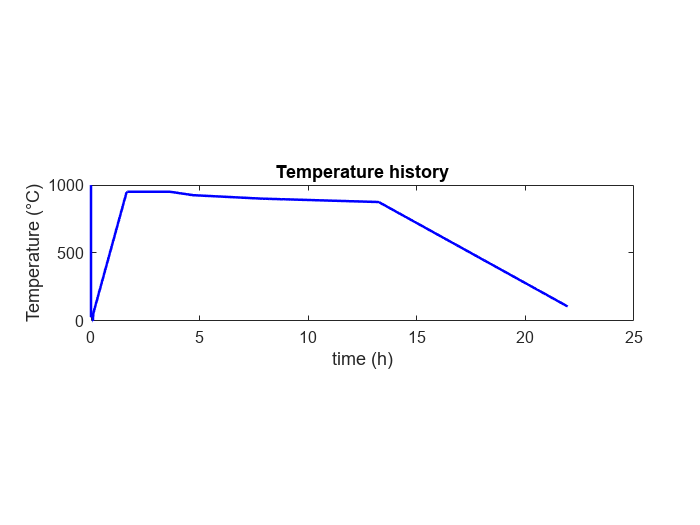


LineColor1 = 'b';
LineColor2 = 'r';
LineWidth=1.5;

Tel1=readmatrix("TEMP_el1.csv");
% Tel2=readmatrix("TEMP_el2.csv");

Bel1=readmatrix("Beta_el1.csv");
% Bel2=readmatrix("Beta_el2.csv");

Ael1=readmatrix("alpha_el1.csv");
% Ael2=readmatrix("alpha_el2.csv");

APel1=readmatrix("mart_alpha_el1.csv");
% APel2=readmatrix("mart_alpha_el2.csv");

LTel1=readmatrix("lath_thick_el1");

time=readmatrix("time.csv");
time=time+0.2;



figure()
plot(time/3600,Tel1,LineColor1,'LineWidth',LineWidth)
title('Temperature history')
ylabel('Temperature (°C)')
xlabel('time (h)')
ylim([0 1000])
pbaspect([4 1 1])

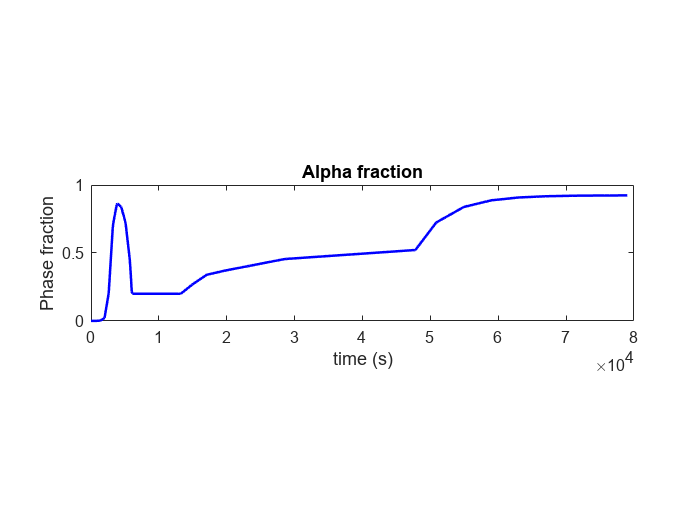




figure()
plot(time,Ael1,LineColor1,'LineWidth',LineWidth)
ylabel('Phase fraction')
xlabel('time (s)')
title('Alpha fraction')
pbaspect([4 1 1])

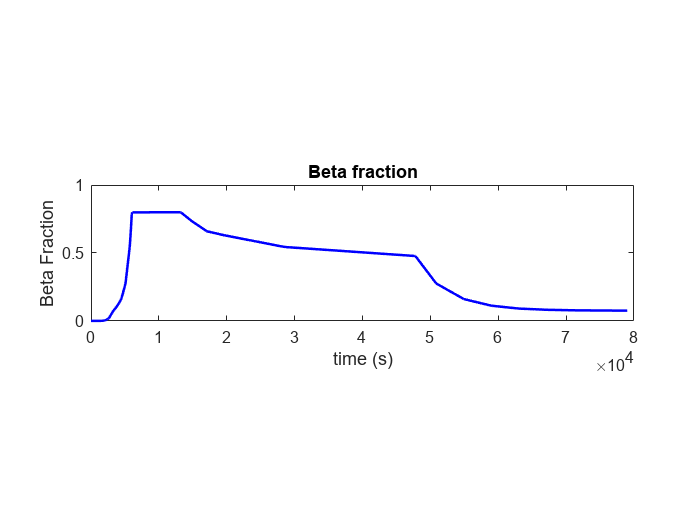


figure()
plot(time,Bel1,LineColor1,'LineWidth',LineWidth)
ylabel('Beta Fraction')
xlabel('time (s)')
title('Beta fraction')
pbaspect([4 1 1])
ylim([0 1])

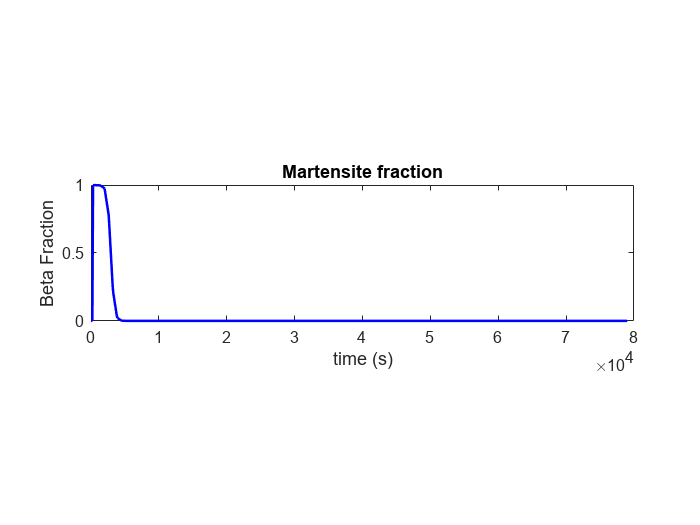


figure()
plot(time,APel1,LineColor1,'LineWidth',LineWidth)
ylabel('Beta Fraction')
xlabel('time (s)')
title('Martensite fraction')
pbaspect([4 1 1])

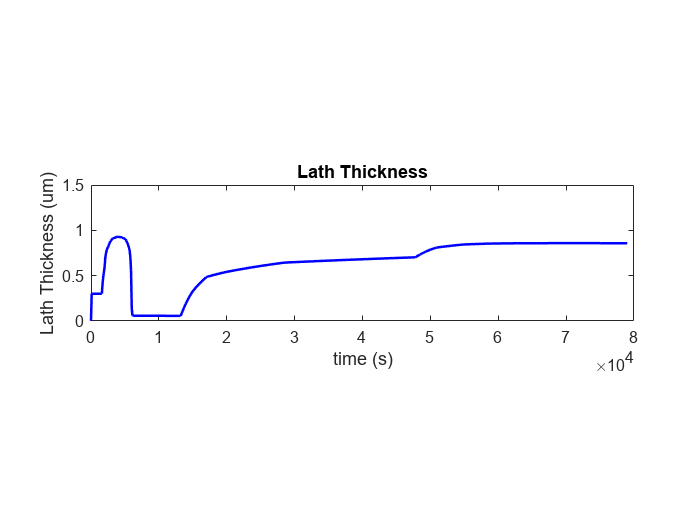


figure()
plot(time,LTel1,LineColor1,'LineWidth',LineWidth)
ylabel('Lath Thickness (um)')
xlabel('time (s)')
title('Lath Thickness')
pbaspect([4 1 1])
% xlim([40000 70000])
ylim([0 1.5])